## ** AERO40003 Computing and Numerical Methods 1**

## **Coursework Project 2019-2020**

## **Dr. Maria Ribera Vicent & Dr. Elnaz Naghibi**

## **Due Date: 20 March 2020**

# PART 1 - MATLAB  [50%]

### Conduction: Temperature distribution on a 2-dimensional plate.   

There are three basic modes in which heat is transferred: conduction, convection and radiation. Conduction is the transfer of heat by virtue of the temperature gradients in the medium (you will learn more about heat transfer soon in your *Thermodynamics and Heat Transfer* module).

The heat conduction equation can be used to calculate the variation of temperature on the plate as a function of time, and after some assumptions  (i.e. constant thermal conductivity) it simplifies to:

$\frac{\partial T}{\partial t}=\alpha \left( \frac{\partial^2 T}{\partial x^2}+\frac{\partial^2 T}{\partial y^2} \right)$       (1)

where $\alpha$ is the thermal diffusivity of the material.

The time derivative can be discretise with some time step $\Delta t$ and equation (1) can be rewritten as:

$T(t+\Delta t) = T(t) + \alpha \left( \frac{\partial^2 T}{\partial x^2}+\frac{\partial^2 T}{\partial y^2} \right)$       (2)

The spatial derivatives can also be approximated by finite differences, so that:

$\frac{\partial^2 T}{\partial x^2} \approx \frac{T(x-\Delta x,y) - 2 T(x,y) + T(x+\Delta x,y)}{\Delta x ^2}$           (3)


$$\frac{\partial^2 T}{\partial y^2} \approx \frac{T(x,y-\Delta y) - 2 T(x,y) + T(x,y+\Delta y)}{\Delta y ^2}$$


To solve the conduction equation above, all that is missing are the initial condition at time zero and/or some boundary conditions defining the temperature at the walls of the plate.

#### Part (a) [20%]

Consider a rectangular plate of a conductive material with dimensions w = 2m and h = 1m. Initially, this plate is at ambient temperature, 273K. Choose an adequate spatial discretisation for your domain.

The sides of the plate are suddenly and instantaneously heated. The left side of the plate is heated to 500K; the top side is heated to 400k; the bottom side is at 420K, while the right side as at 350K.

Plot the discretised domain and the initial temperature profile (use an adequate plotting function such as surf or contourf).

Iterate for 10 minutes. Use a time step of 0.1 seconds.

Display the temperature profile after 1 minute, 3 minutes, 5 minutes and 10 minutes.

Put labels and a title in your plots, and save as JPEG figures. 

Take $\alpha = 10^{-3} m^2/s$. 

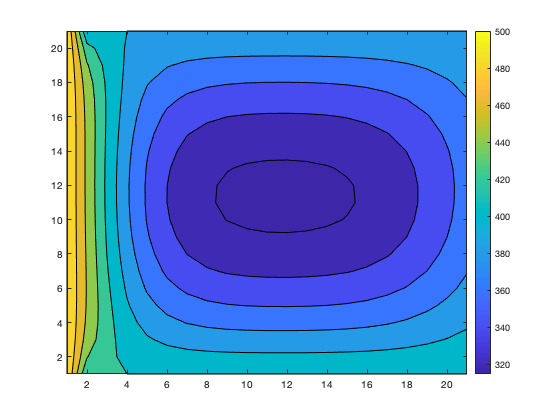


%number of nodes in  each direction
%note: 21 nodes results in x discretisation = 0.1m and y discretisation =
%0.05m
step = 21;


%setting up temperature nodes matrix 
T = ones(step,step)*273;
T(1:step) = 500;
T(step+1:step:(step*step)) = 420;
T(step*2:step:step*step)=400;
T(step*(step-1)+2:1:(step*step)-1) = 350;


%4 time variables
time_1 = 60/0.1; time_2 = 180/0.1; time_3 = 300/0.1; time_4 = 600/0.1;

%saving the plots
one = figure;
temp = plate_temp(T,time_1,step);
contourf(temp);
colorbar
saveas(one, "Temp_after_1min.jpg")

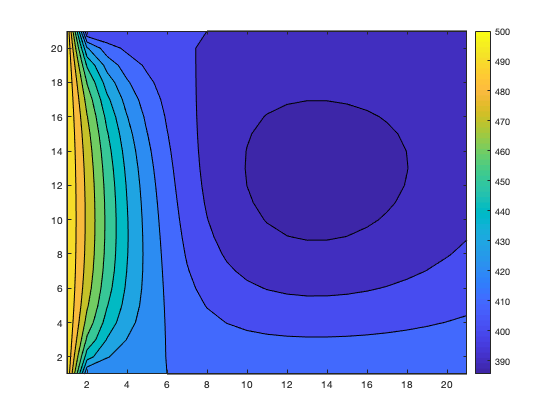


two = figure;
temp = plate_temp(T,time_2,step);
contourf(temp);
colorbar
saveas(two, "Temp_after_3min.jpg")

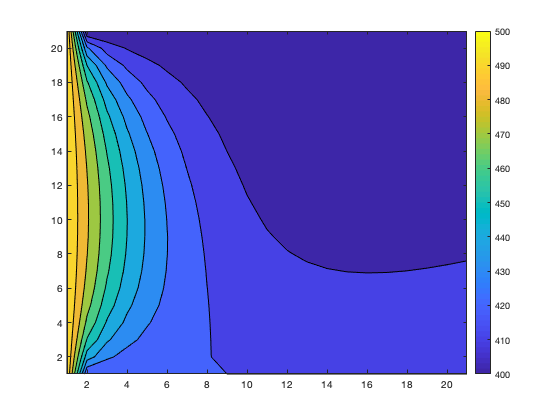


three = figure;
temp = plate_temp(T,time_3,step);
contourf(temp);
colorbar
saveas(three, "Temp_after_5min.jpg")

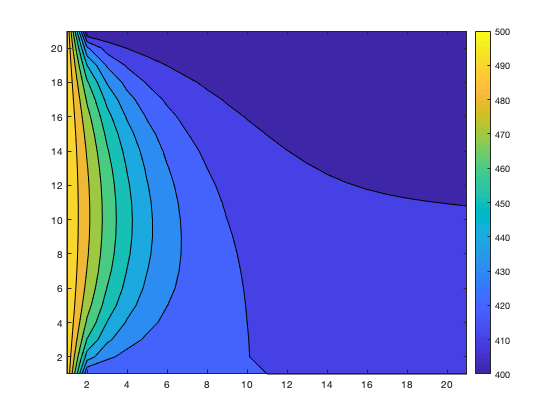


four = figure;
temp = plate_temp(T,time_4,step);
contourf(temp);
colorbar
saveas(four, "Temp_after_10min.jpg")

#### Part (b) [10%]

Use the function **fit** to obtain a surface to approximate the data in part (a) after 1 minute. There are many[ types of surface fit](https://uk.mathworks.com/help/curvefit/list-of-library-models-for-curve-and-surface-fitting.html)  possible, try with two different types of your choice (i.e. interpolant, polynomial...). Make sure you output the goodness-of-fit statistics of each surface approximation (see the [documentation](https://uk.mathworks.com/help/curvefit/fit.html) for explanation). 

Which of the two gives the better approximation to your data? Explain briefly. 

Plot both surfaces in separate plots, with the corresponding labels and title. Save as a JPEG file.

In a single figure, plot the values of both functions along the line y=0.5 for all values of x (i.e., the line that splits the plate in half), along with the original points from part (a) at the same location. Make sure you add labels, title and a legend. Save the figures as JPEG file.

Hints: 

- the function **fit** requires the input in columns, so reorganise your data to have both the coordinates and the temperature each in a column vector. 

- save the data above corresponding to the first minute in a separate array to use later.

- The output of the **fit** function is a *sfit* object, which works similarly to function handles. You can read more about them in [here](https://uk.mathworks.com/help/curvefit/sfit.html).


%getting the temp after 1 minute
min_1 = plate_temp(T,time_1,21);

%preparing the data for the fit function
X = (0:dx:w);
Y = (0:dy:h);
[Xout, Yout, Zout] = prepareSurfaceData(X,Y,min_1);

%fits
[fit_1, goodness_1,output_1] = fit([Xout Yout],Zout,"cubicinter");
[fit_2, goodness_2] = fit([Xout Yout], Zout, "poly33");

%goodness of the fits sum squared error
fprintf("SSE of cubic interpolated: %e", goodness_1.sse)

SSE of cubic interpolated: 0.000000e+00

fprintf("SSE of poly33: %e", goodness_2.sse)

SSE of poly33: 6.886389e+04

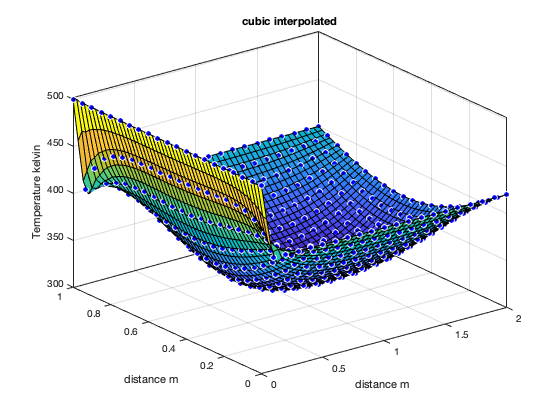

%SSE is larger for the poly33. Interpolation gives a 0 error when
%measureing against the exact node points.

%z values i.e. temps of the different fits
Zhat_1 = fit_1(X,0.5);
Zhat_2 = fit_2(X,0.5);
Zhat_3 = min_1(11,:);


fig1 = figure;
plot(fit_1, [Xout, Yout], Zout)
title("cubic interpolated")
xlabel("distance m")
ylabel("distance m ")
zlabel("Temperature kelvin")
saveas(fig1, "Surface_cubic_interpolated.jpg")

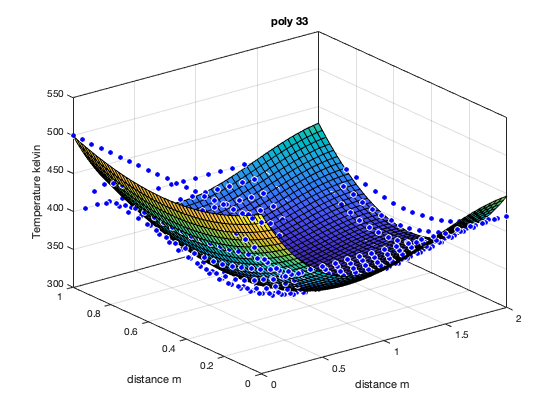


fig2 = figure;
plot(fit_2, [Xout, Yout], Zout)
title("poly 33")
xlabel("distance m")
ylabel("distance m")
zlabel("Temperature kelvin")
saveas(fig2, "Surface_Poly33.jpg")

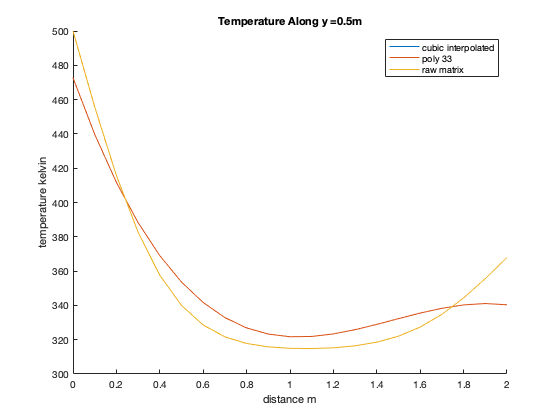


fig_3 = figure;
hold on
plot(X,Zhat_1)
plot(X,Zhat_2)
plot(X,Zhat_3)
title("Temperature Along y =0.5m")
xlabel("distance m")
ylabel("temperature kelvin")
legend("cubic interpolated","poly 33", "raw matrix")
saveas(fig_3, "Comparison_of_Models.jpg")

#### Part (c) [10%]

Use the **fmincon** function to find the minimum temperature in the plate above, and the location where it occurs, in the same snapshot after 1 minute. (Note: we are not applying any constraints other than the bounds on the x and y dimensions so that the search takes place within the plate; all the other input to fmincon must be defined, but can be an empty array - see [documention](https://uk.mathworks.com/help/optim/ug/fmincon.html) for examples).

Start your search from the point [2,1], corresponding to the upper right corner.

Display your answer neatly (you may use **disp** or **fprintf** but either case format your string nicely)

Hint: remember you can use the* sfit* object as a function handle when using** fmincon**. 

***OPTIONAL, for fun :)***

*You can play with the options to fmincon, for instance you can display all the iterations in the search.*

*You could also explore what other outputs you can get from the function in structures that group different values of interest, such as the gradient of the function at the solution or the Lagrange multipliers.*

x = fmincon(@(x) fit_1(x),[2,1],[],[],[],[],[0,0],[2,1]);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



temp_min = fit_1(x)

temp_min = 314.6653

fprintf("position m : x=%f, y=%f", x(1),x(2))

position m : x=1.071748, y=0.517856

fprintf("Min Temperature kelvin: %e", temp_min)

Min Temperature kelvin: 3.146653e+02

f = 'A'

SNR target for BER A

#### Part (d) [10%] 

Now repeat the above with different boundary conditions. Rather than a uniform temperature for each side, we consider the entire plate at ambient temperature except the following nodes/regions that will be heated to 500K:

A = T(0,0-0.45) = 500K

B = T(0,0.75-1) = 500K

C = T(1-1.6,0) = 500K

D = T(1-0.7,1)= 500K

E = T(1.2-1.7,1)= 500K

F = T(2,0.3-0.6) = 500K

Rather than repeating the entire code again, you may **choose one** of the following two options: 

- Ask the user which case to run, then use a switch to define the boundary conditions.   or

- Use a loop to repeat the process for each set of boundary conditions.

Do the approximation functions you used for part (b) work as well in this part? If not, consider using a higher degree polynomial or other functions to give you a better fit.

Start the search of the minimum from [0,1], corresponding to the top left corner. 

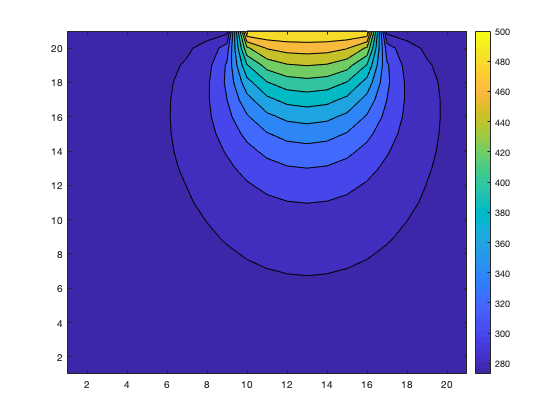

clc
clear

step = 21;

T = ones(step,step)*273;
T(11:step) = 500;
T(step+1:step:(step*step)) = 273;
T(step*10:step:step*16)=273;
T(step*(step-1)+2:1:(step*step)-1) = 273;

T(step*(step-1)+2+8:1:(step*step)-6) = 273;




n = input("which input would you like A,B,C,D,E,F as seen in the question above: ",'s');

switch n
    case 'A'
        T = ones(step,step)*273;
        T(1:9) = 500;
        T(step+1:step:(step*step)) = 273;
        T(step*2:step:step*step)=273;
        T(step*(step-1)+2:1:(step*step)-1) = 273;
    case 'B'
        T = ones(step,step)*273;
        T(15:step) = 500;
        T(step+1:step:(step*step)) = 273;
        T(step*2:step:step*step)=273;
        T(step*(step-1)+2:1:(step*step)-1) = 273;
        
    case 'C'
        T = ones(step,step)*273;
        T(15:step) = 273;
        T(step+1:step:(step*step)) = 273;
        T(step*10:step:step*16)=500;
        T(step*(step-1)+2:1:(step*step)-1) = 273;
    
    case 'D'
        T = ones(step,step)*273;
        T(15:step) = 500;
        T(step+1:step:(step*step)) = 273;
        T(step*2:step:step*step)=273;
        T(step*(step-1)+2:1:(step*step)-1) = 273;
    
    case 'E'
        T = ones(step,step)*273;
        T(15:step) = 500;
        T(step+1:step:(step*step)) = 273;
        T(step*2:step:step*step)=273;
        T(step*(step-1)+2:1:(step*step)-1) = 273;
    
    case 'F'
        T = ones(step,step)*273;
        T(15:step) = 273;
        T(step+1:step:(step*step)) = 273;
        T(step*2:step:step*step)=273;
        T(step*(step-1)+2:1:(step*step)-1) = 273;
        T(step*(step-1)+2+8:1:(step*step)-6) = 500;
end

time_1 = 60/0.1; time_2 = 180/0.1; time_3 = 300/0.1; time_4 = 600/0.1;
w =2;
h=1;
dx = w/(step-1);
dy =h/(step-1);

%saving the plots
one = figure;
temp = plate_temp(T,time_1,step);
contourf(temp);
colorbar
saveas(one, "Temp_after_1min_user_defined.jpg")

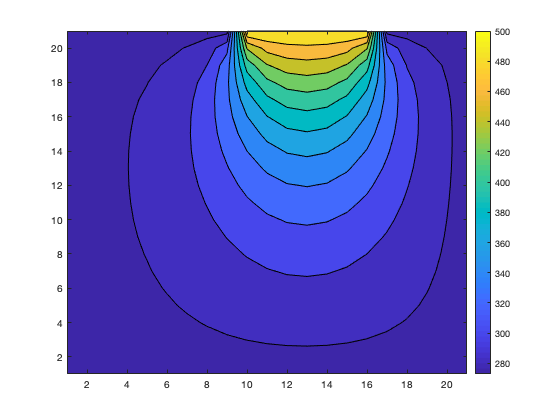


two = figure;
temp = plate_temp(T,time_2,step);
contourf(temp);
colorbar
saveas(two, "Temp_after_3min_user_defined.jpg")

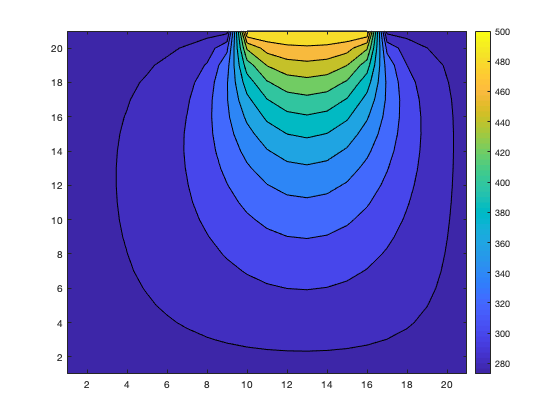


three = figure;
temp = plate_temp(T,time_3,step);
contourf(temp);
colorbar
saveas(three, "Temp_after_5min_user_defined.jpg")

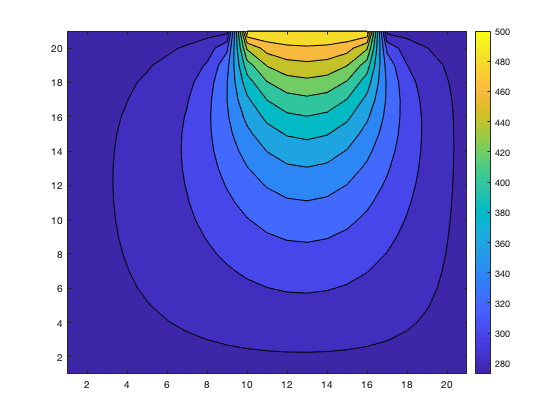


four = figure;
temp = plate_temp(T,time_4,step);
contourf(temp);
colorbar
saveas(four, "Temp_after_10min_user_defined.jpg")


%getting the temp after 1 minute
min_1 = plate_temp(T,time_1,21);

%preparing the data for the fit function
X = (0:dx:w);
Y = (0:dy:h);
[Xout, Yout, Zout] = prepareSurfaceData(X,Y,min_1);

%fits
[fit_1, goodness_1,output_1] = fit([Xout Yout],Zout,"cubicinter");
[fit_2, goodness_2] = fit([Xout Yout], Zout, "poly33");

%goodness of the fits sum squared error
fprintf("SSE of cubic interpolated: %e", goodness_1.sse)

SSE of cubic interpolated: 0.000000e+00

fprintf("SSE of poly33: %e", goodness_2.sse)

SSE of poly33: 2.962368e+05

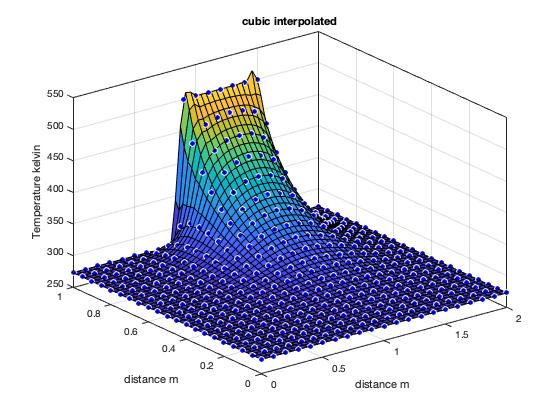


%z values i.e. temps of the different fits
Zhat_1 = fit_1(X,0.5);
Zhat_2 = fit_2(X,0.5);
Zhat_3 = min_1(11,:);


fig1 = figure;
plot(fit_1, [Xout, Yout], Zout)
title("cubic interpolated")
xlabel("distance m")
ylabel("distance m ")
zlabel("Temperature kelvin")
saveas(fig1, "Surface_cubic_interpolated_user_defined.jpg")

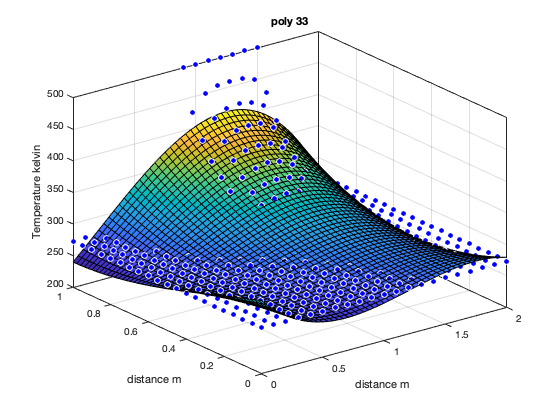


fig2 = figure;
plot(fit_2, [Xout, Yout], Zout)
title("poly 33")
xlabel("distance m")
ylabel("distance m")
zlabel("Temperature kelvin")
saveas(fig2, "Surface_Poly33_user_defined.jpg")

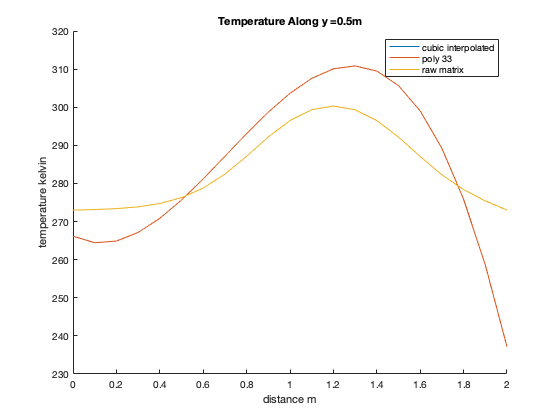


fig_3 = figure;
hold on
plot(X,Zhat_1)
plot(X,Zhat_2)
plot(X,Zhat_3)
title("Temperature Along y =0.5m")
xlabel("distance m")
ylabel("temperature kelvin")
legend("cubic interpolated","poly 33", "raw matrix")
saveas(fig_3, "Comparison_of_Models_user_defined.jpg")


x = fmincon(@(x) fit_1(x),[2,1],[],[],[],[],[0,0],[2,1]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

temp_min = fit_1(x)

temp_min = 272.9997

fprintf("position m : x=%f, y=%f", x(1),x(2))

position m : x=0.175573, y=0.000000

fprintf("Min Temperature kelvin: %e", temp_min)

Min Temperature kelvin: 2.729997e+02

Hints: 

- make sure you don't overwrite your saved figures.

- you could also use your condition to have the different starting values in each case.

***Some general tips:***

- make sure you don't overwrite your figures!

- look at your results and see if they make sense. If not, what can you change? the step size? the type or degree of the interpolating function? While an exact interpolant for part (d) might be difficult, at least think about it.

- read the markscheme and make sure that your code is well commented and indented.

- when asked to save the figures, remember to put them in your folder together with your livescripts, before zipping and uploading the compressed folder. 